## Generating Independent Draws

rng(0);
m = 100000;
z = rand(1,m);
for i=1:1:m
    if z(1,i) > 0.5
        z(1,i) = sqrt(2*z(1,i) - 1);
    else
        z(1,i) = -1*(sqrt(1-2*z(1,i)));
    end
end

The above code will generate independent draws similar to$P_X(.)$

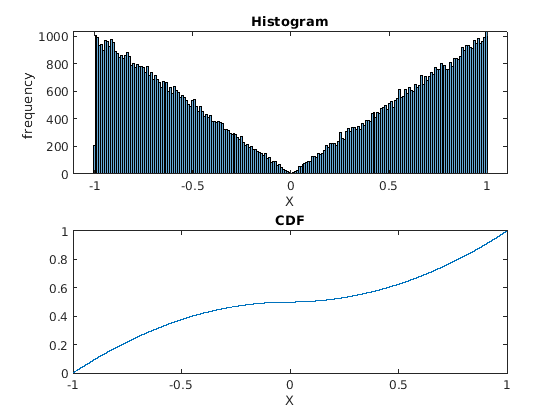

t=sort(z);
a = unique(t);
freq = zeros(1,length(a));
for i=1:1:length(a)
    freq(1,i) = sum(t(1,:)==a(1,i));
end
freq_cdf = cumsum(freq)./m;

hold on;
subplot(2,1,1);
histogram(z,200);
subplot(2,1,2);
plot(a,freq_cdf);
hold off;

subplot(2,1,1)
xlim([-1.11 1.10])
ylim([0 1029])
title("Histogram")
xlabel("X")
ylabel("frequency ")
subplot(2,1,2)
xlim([-1.00 1.00])
ylim([0.00 1.00])
title("CDF")
xlabel("X")